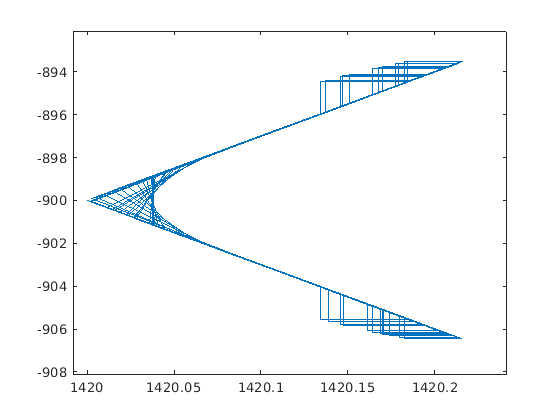

clear all;
% parameters
dt = 0.1;
c0 = 1450;
lamda = 0.016;
h = 3000;
horizonrange = 30000;
total_time = horizonrange/c0;

t = 0:dt:total_time;

theta0 =1*pi/180;
zs = 900;
x = zeros(size(t));
z = zeros(size(t));
theta = zeros(size(t));
c = zeros(size(t));

x(1) = 0;
z(1) = zs;

theta(1) = theta0;
c(1) = velocity(z(1), c0, lamda);
snails_constant = cos(theta0)/c0;
for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x(i) = x(i-1) + c(i-1)*dt*cos(theta(i-1));
    z(i) = z(i-1) + c(i-1)*dt*sin(theta(i-1));
    c(i) = velocity(z(i), c0, lamda);
    
    
    snails_constant = cos(theta(i-1))/c(i-1);
    
    if snails_constant*c(i) <= 1
        theta(i) = sign(theta(i-1))*acos(snails_constant*c(i));
    else
        z(i) =z(i-1) ;
        c(i) = c(i-2);
        theta(i) = -theta(i-2);
        %disp(i)
        %disp(theta(i))
        %disp(theta(i))
    end
    
    
    if z(i) < 0 
        z(i) =z(i-1) ;
        c(i) = c(i-2);
        theta(i) = -theta(i-2);
    elseif z(i)>8000
        z(i) =z(i-1) ;
        c(i) = c(i-2);
        theta(i) = -theta(i-2);
    end
    
    
    
end


plot(c,-z)

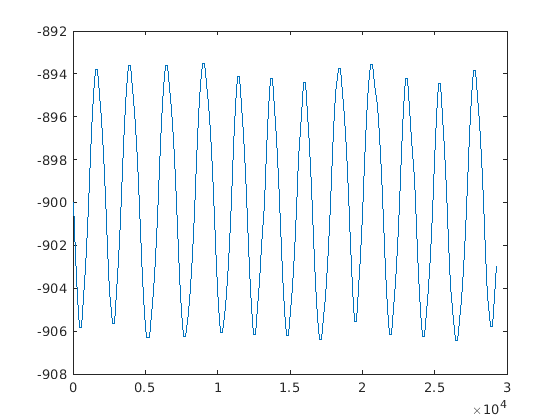

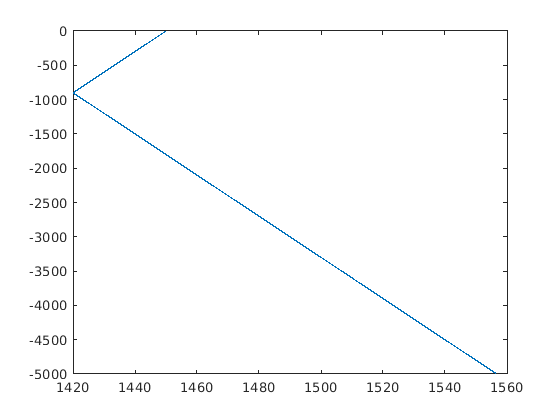

plot(x,-z)

function c= velocity(z,l,q)
    z2 = 900;
    c0 = 1450;
    c1 = 1420;
    if z<z2;
        m = (c0-c1)/(-z2);
        c = m*z + c0;
    elseif z>=z2
        m = (c0-c1)/(z2);
        c = m*z + (2*c1-c0);
    end
end

%function c = velocity(z, c0, lamda)
 
%c = c0 + lamda*z;
%end